# **DATASET: CIRCLE**

clear 
clc

#### Load the file

circle_mat = load('Circle.mat');

% Display the structure of the file
disp(circle_mat);

    X: [900×2 double]



% Extract the matrix of points
X = circle_mat.X;

#### Plot the points

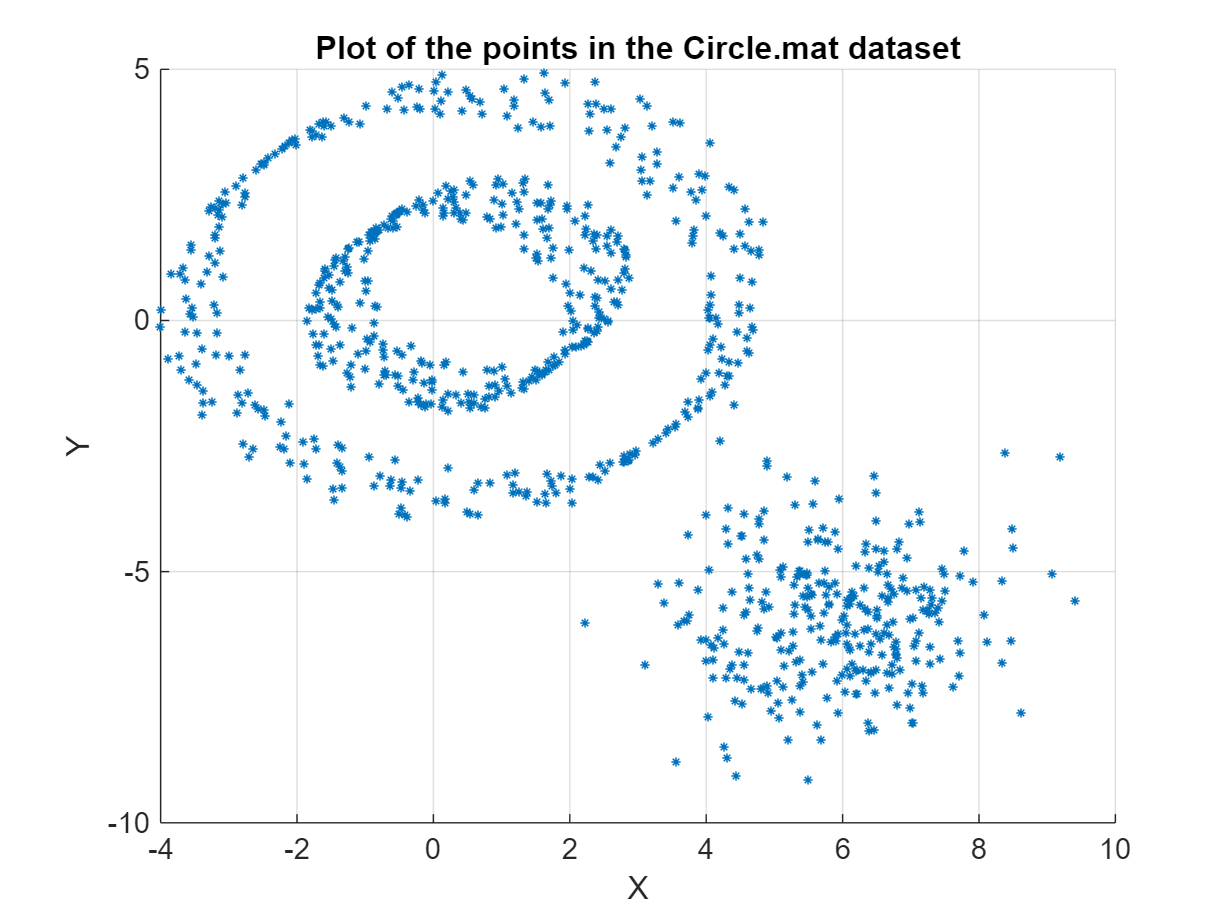

figure;
scatter(X(:,1), X(:,2), 10, Marker='*');
xlabel('X'); 
ylabel('Y'); 
title('Plot of the points in the Circle.mat dataset');
grid on;

## 1. Similarity matrix and adjacency matrix

Three independent simulations of the script were carried out, with k set to 10, 20 and 40, respectively. The results presented in this script were obtained with a value of k fixed at 10. To analyse other values of k, it is simply necessary to change the value of k in the source code and re-run the script.

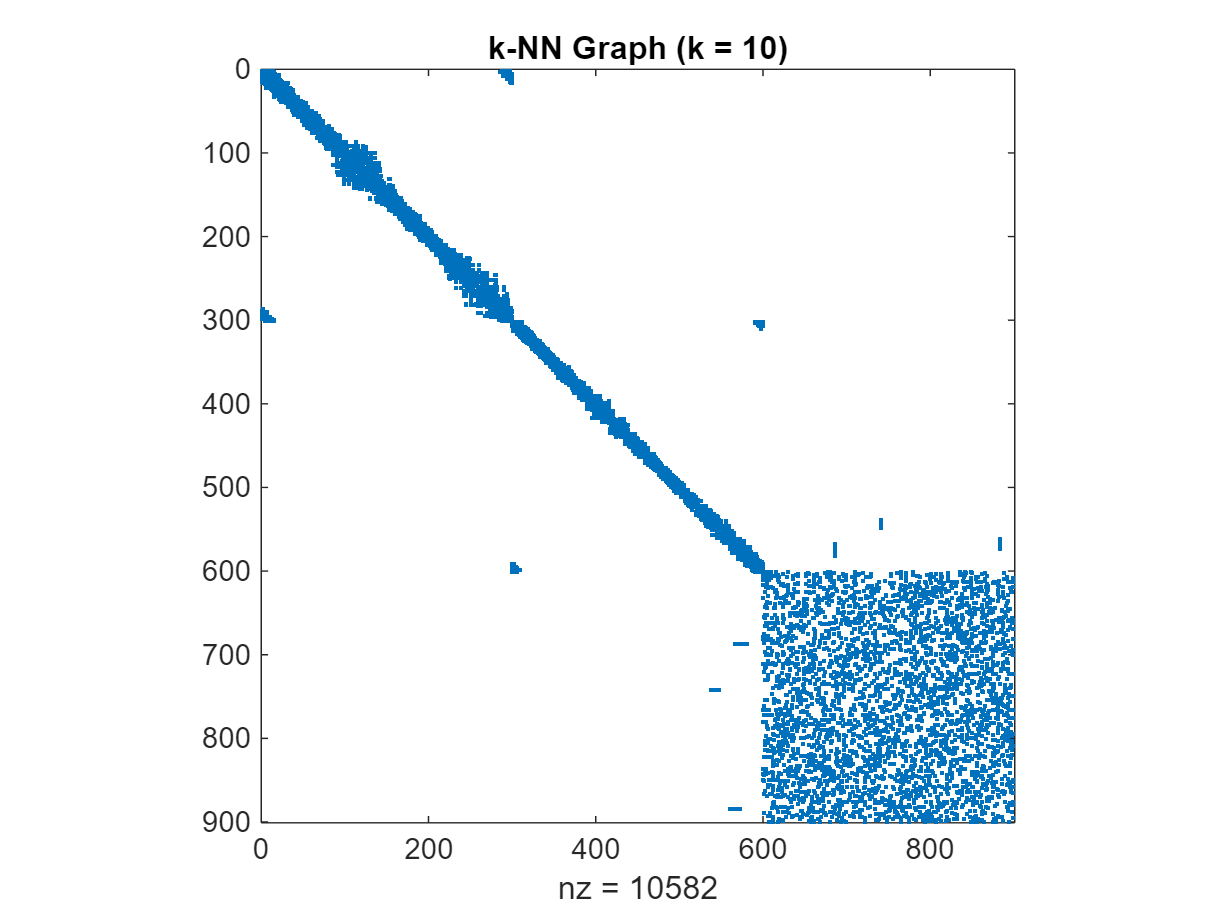

k_values = [10, 20, 40];
k = 10;
% Construct the k-nearest neighborhood similarity graph and its adjacency matrix W
W = knn_graph(X, k);

% Visualize the graph using its similarity matrix
figure;
spy(W); 
title(['k-NN Graph (k = ', num2str(k), ')']);

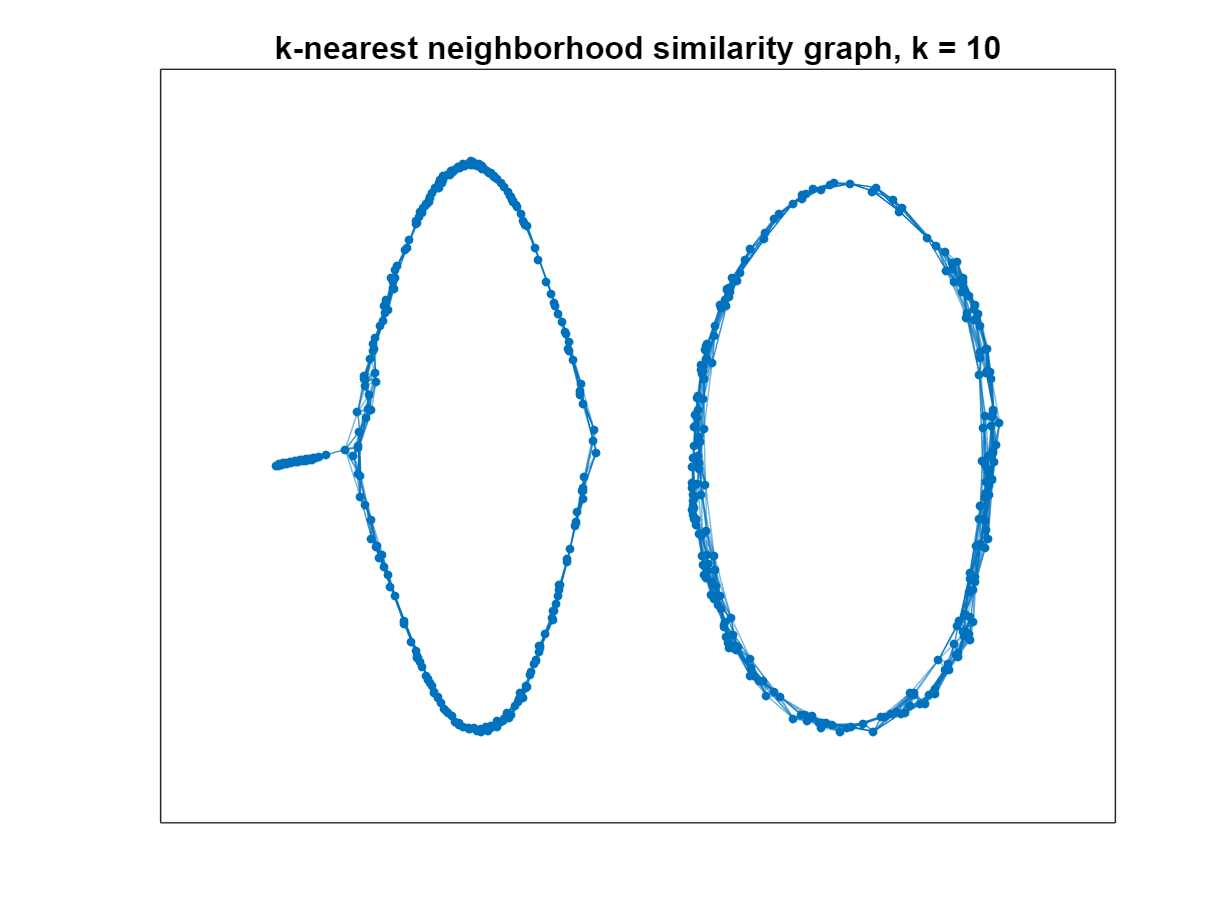

% Store W as a sparse matrix
W = sparse(W);

% Visualize the graph G corresponding to the adjacency matrix W
G = graph(W);
figure;
plot(G);
title(['k-nearest neighborhood similarity graph, k = ', num2str(k)]);

## 2. Construct the degree matrix D and the Laplacian matrix L

N = size(W, 1);

% Inizialize the degree matrix D
D = zeros(N, N); 

% The degree of each point is given by the sum of the elements of each row in W
D = diag(sum(W, 2));

% Save D in a sparse format
D = sparse(D);

% Compute the Laplacian matrix L
L = D - W;

if issparse(L) % issparse(L)==1 means that L is stored in a sparse format
    disp("The matrix L is stored in a sparse format")
end

The matrix L is stored in a sparse format


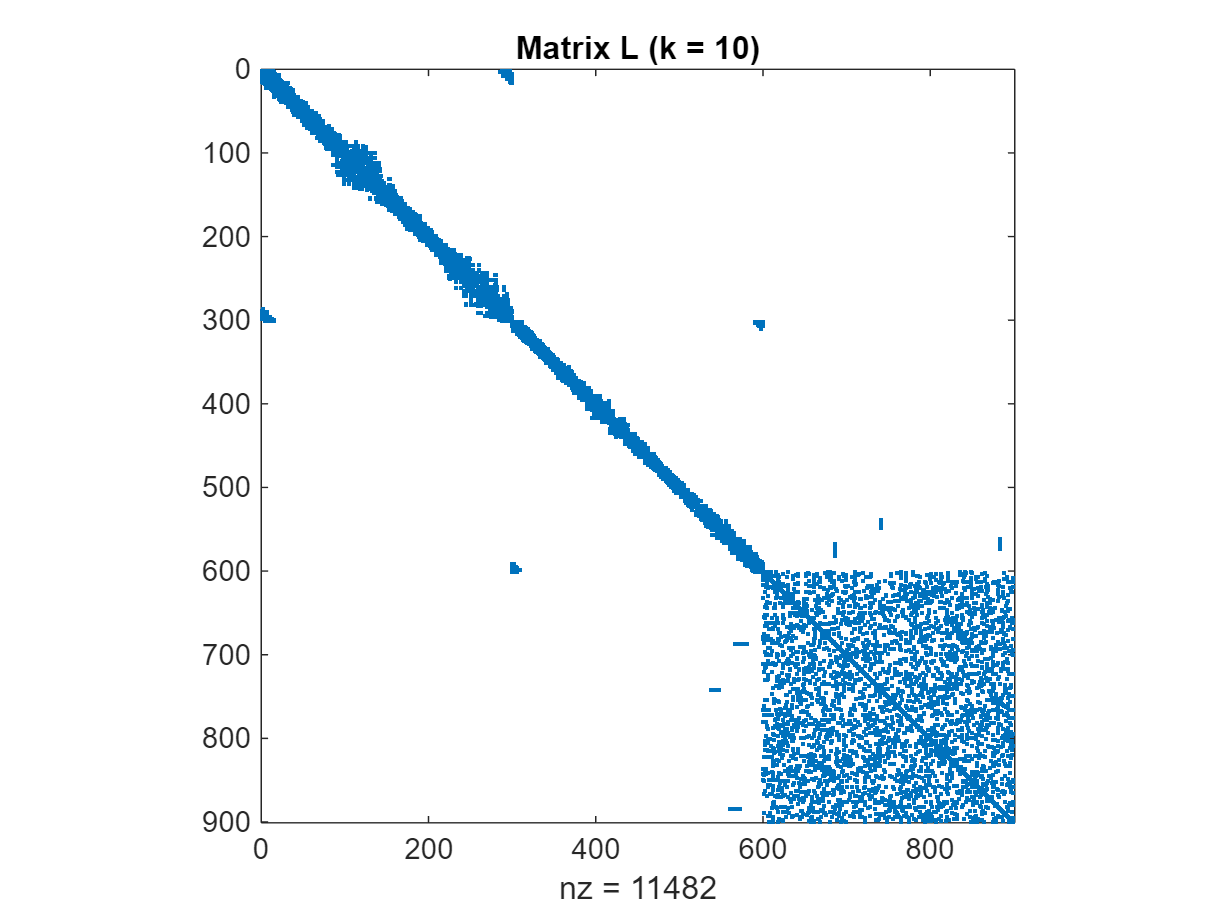

% Plot the Laplacian matrix L
figure;
spy(L);  
title(['Matrix L (k = ', num2str(k), ')']);

## 3. Compute the number of connected components of the similarity graph

% The points with the same number belong to the same connected component
bins = conncomp(G); 

% Number of connected components
num_components = max(bins);

% Display the result
disp(['Number of connected components: ', num2str(num_components)]);

Number of connected components: 2


## 4 - 5. Compute eigenvalues and eigenvectors

This script implements two methods for computing the M smallest eigenvalues and their corresponding eigenvectors: the deflation method and the inverse power method. Currently, the script is configured to use the deflation method. The first eigenvector is manually set as `eigvects(:, 1) = ones(N,1)/norm(ones(N,1))` , reflecting the known eigenvector of all ones for the Laplacian matrix. Alternatively, the first eigenvalue and eigenvector can be computed using the inverse power method by uncommenting the line `[eigvalues(1), eigvects(:, 1)] = invpower_method(L, v(1 : end), maxIter, relTol)` and commenting out the line that manually sets the first eigenvector.

% Set a number M of values to be computed (later it will be changed)
M = 10;

% Inizialize the eigenvalues vector and the eigenvectors matrix
eigvalues = zeros(M, 1);
eigvects = zeros(N, M);  

% Choose the vector v that will be used for the inverse power method or deflation_method
v = 0.5 * ones(N, 1);  
v(1:2:N) = -0.5;

% Max iterations in the power method
maxIter = 1000;
% Relative tolerance
relTol = 1e-10; 

% A known fact from theory is that L is semi pos def and has at least one
% eigenvalue = 0 and that the vector of all ones is a corresponding
% eigvalues(1) = 0;
eigvects(:, 1) = ones(N,1)/ norm(ones(N,1));

% Or use the inverse power method to compute them 
% [eigvalues(1), eigvects(:, 1)] = invpower_method(L, v(1:end), maxIter, relTol);

% Compute the reamining eigenvetors and eigenvalues
[eigvalues, eigvects, residualnorms] = deflation_method(L, v, eigvects, eigvalues,M, maxIter, relTol);

% Check how good the approximation is by comparing with eigs function of
% Matlab
[mat_eigvects, mat_eigs] = eigs(L, M, 'smallestabs');

norm(eigvalues - diag(mat_eigs))

ans = 4.1035e-10

#### Now, find the actual number M of eigenvalues that will be used for the clustering algorithm

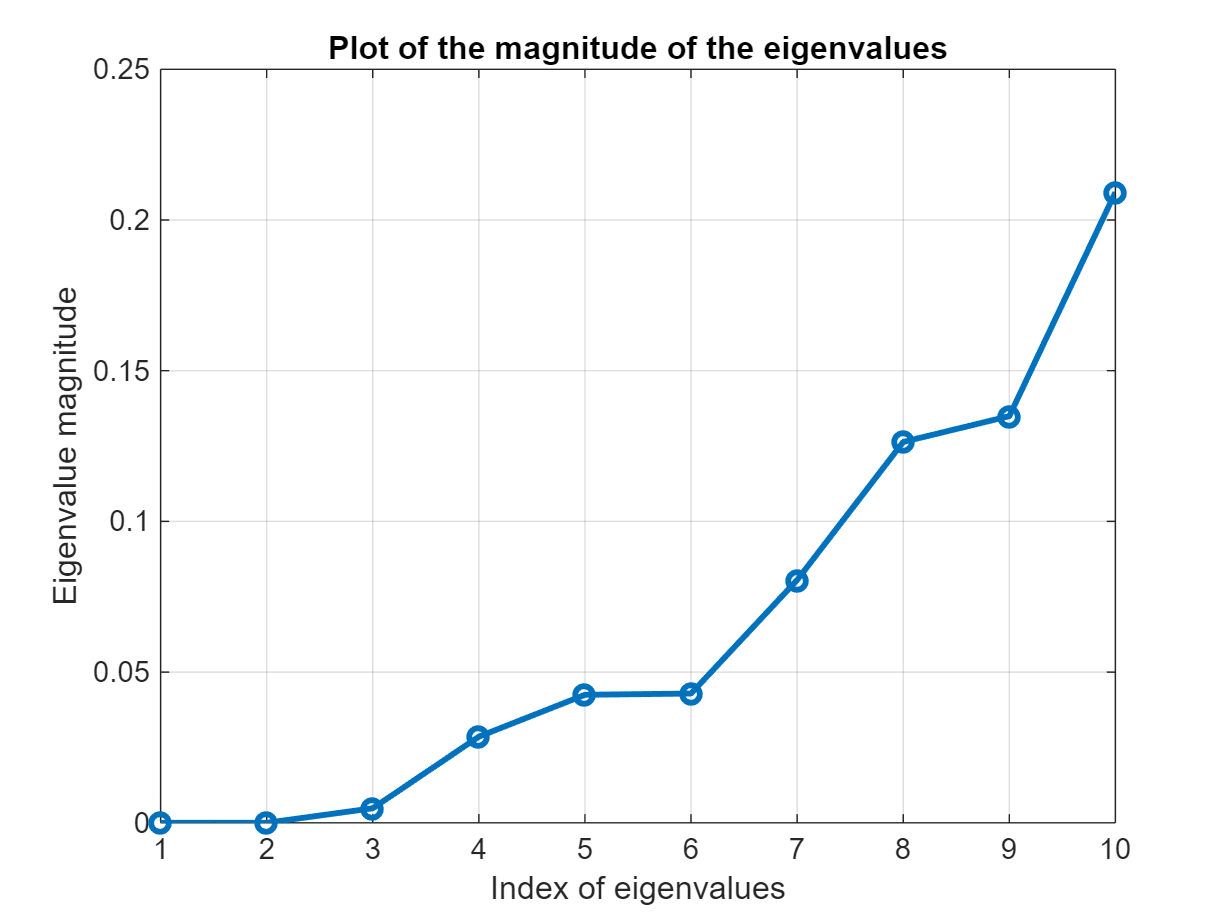

% Plot the computed eigenvalues
x = 1:M;            

figure           
plot(x, eigvalues, '-o', 'LineWidth', 2); 
xlabel('Index of eigenvalues');
ylabel('Eigenvalue magnitude'); 
title('Plot of the magnitude of the eigenvalues'); 
grid on;

#### The suitable number of eigenvalues is either 2 or 3 since eig4 is much larger than eig3 for k=10

M = 2;

% Define the matrix U that will be used for the spectral clustering
U = eigvects(:, 1:M);

## 6 - 7 - 8. Spectral clustering, k means

% Clusterize using k means and obtain the indices (and the centroids) inside the clusters of each point
[idx, C] = kmeans(U, M);

% Assing the original data to the corresponding clusters
A = cell(M, 1);  

for i = 1:N
    % Find the cluster of y_i
    cluster_idx = idx(i); 

    % Assing it to x_i
    A{cluster_idx} = [A{cluster_idx}; X(i, :)];  
end

% Plot of the clusterized data in the original space
X_spect_clust = zeros(N, 3);
X_spect_clust(:, 1: 2) = X;
X_spect_clust(:, 3) = idx;

figure;
markers = ['o', '+', 's'];
gscatter(X_spect_clust(:,1), X_spect_clust(:,2), X_spect_clust(:, 3), [], markers, [], 5); 
title(['Spectral k means in the original dataset with ', num2str(M), ' clusters']);
legend('Cluster 1', 'Cluster 2', 'Cluster 3');

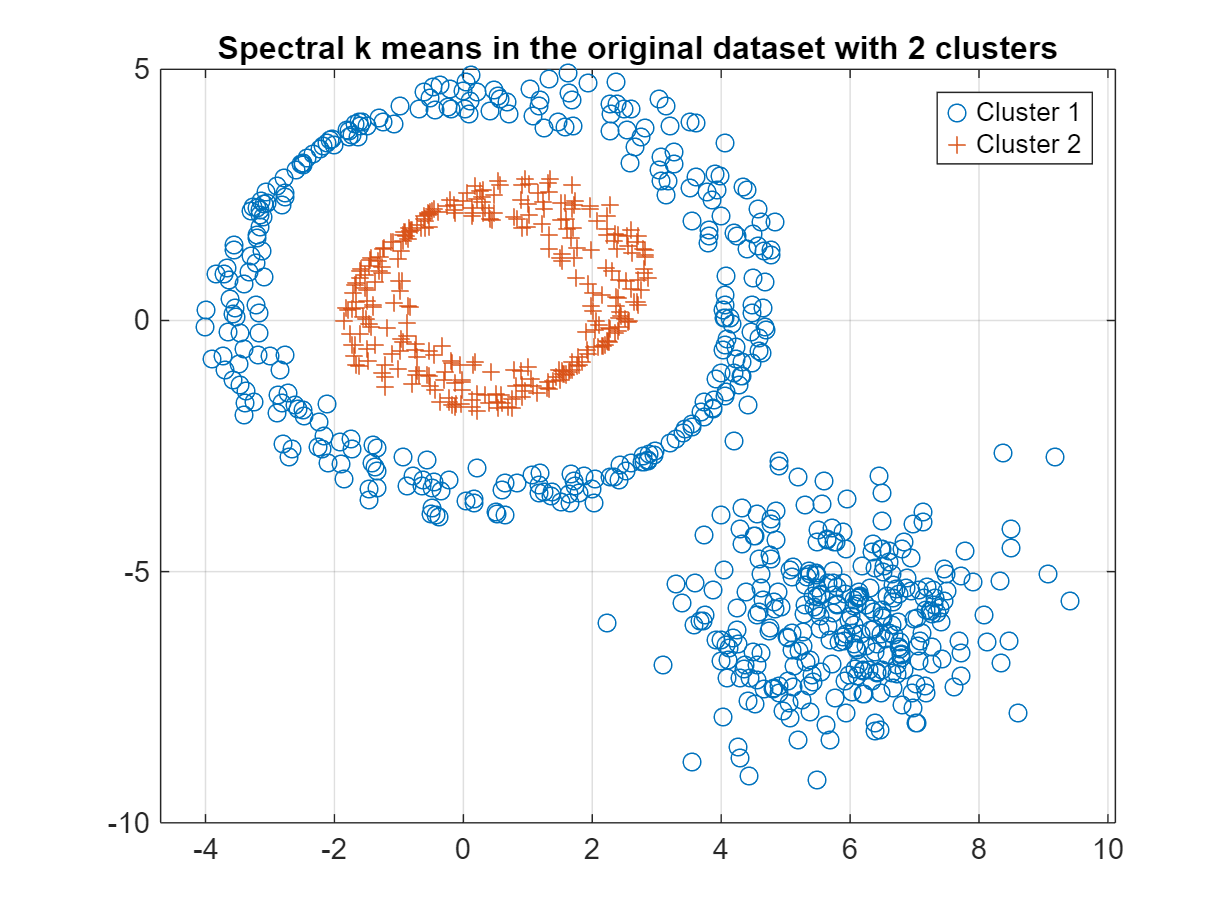

grid on;

## 9.a K MEANS TO THE ORIGINAL DATA

k_value = 2;

% Clusterize the original data 
[idx_k, C_k] = kmeans(X, k_value);

% Add the index to X_kmeans
X_kmeans = zeros(N, 3);
X_kmeans(:, 1: 2) = X;
X_kmeans(:, 3) = idx_k;

figure;
markers = ['o', '+', 's'];
gscatter(X_kmeans(:,1), X_kmeans(:,2), X_kmeans(:, 3), [], markers, [], 5); 
title(['K means applied to the original dataset with ', num2str(k_value), ' clusters']);
legend('Cluster 1', 'Cluster 2', 'Cluster 3');

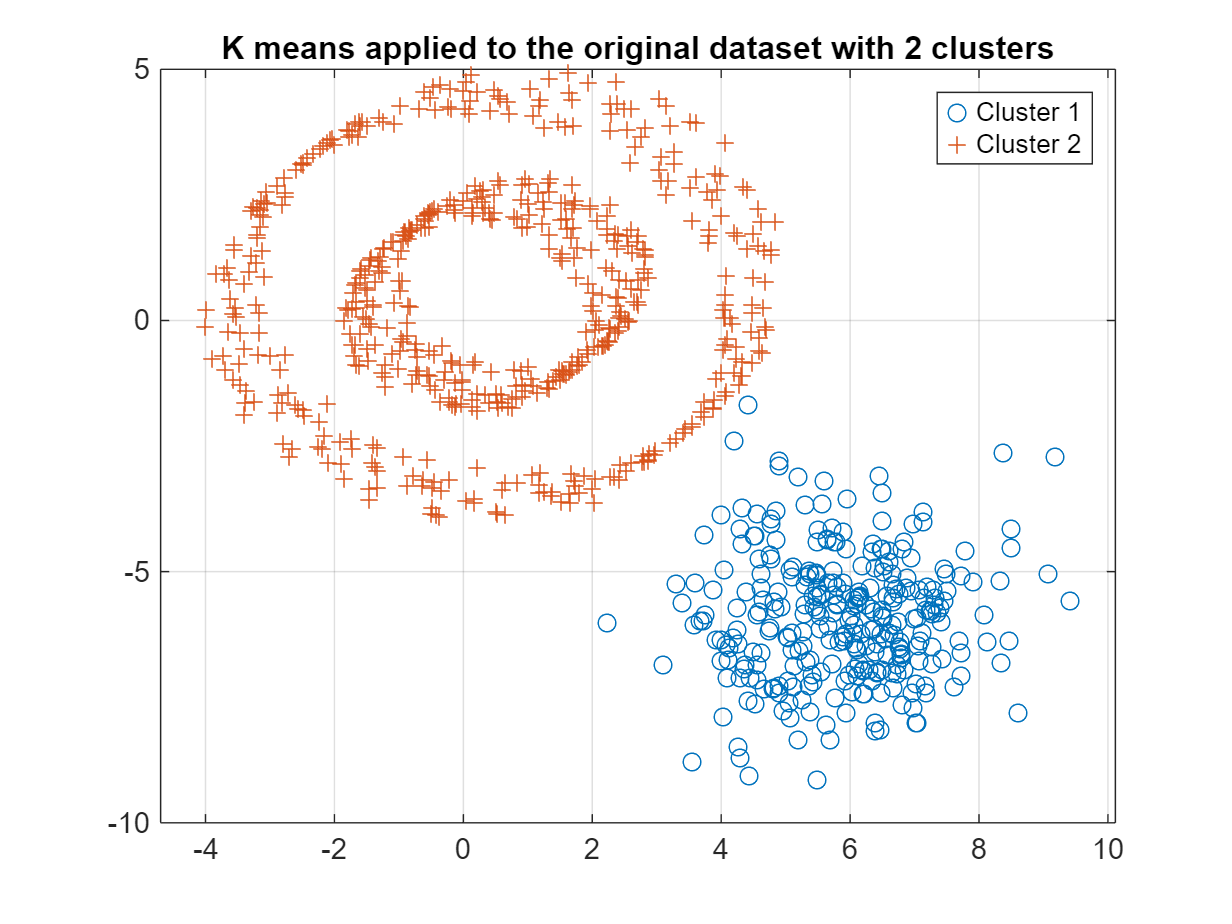

grid on;

## 9.b DBSCAN TO THE ORIGINAL DATA

Apply the DBSCAN algorithm

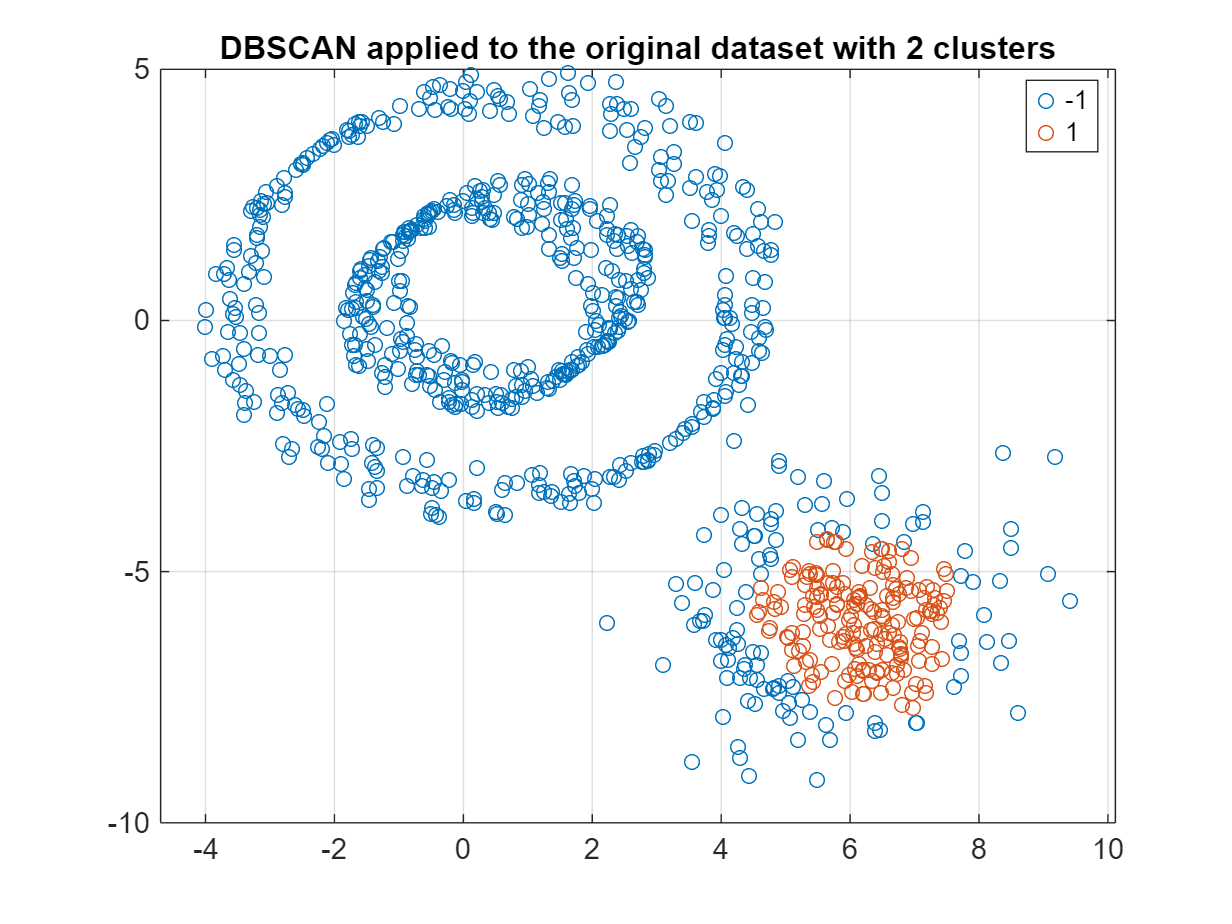

% Neighborhood radius
epsilon = 0.8;
% Minimum points for a cluster
minPts = 45; 

idx_d = dbscan(X, epsilon, minPts);

X_dbscan = zeros(N, 3);
X_dbscan(:, 1: 2) = X;
X_dbscan(:, 3) = idx_d;

figure;
gscatter(X_dbscan(:,1), X_dbscan(:,2), X_dbscan(:, 3), [], 'o', 5);
title(['DBSCAN applied to the original dataset with ', num2str(M), ' clusters']);
grid on;